**E1**

addpath Function\
addpath Data\

addpath Trash\

addpath Legacy\
 
disp("=========================")

disp("Load the data")

Load the data


disp("=========================")


 
x1=load("Series_1.txt");
x2=load("Series_2.txt");
% DOF
f1 = length(x1)-1;
f2 =length(x2)-1;
% Residual
v1 = x1-mean(x1);
v2 = x2-mean(x2);
% STD
s1 = std(v1);
s2 = std(v2);
xbar1= mean(x1);
xbar2=mean(x2);
% T1,T2,Chi,FA
flag="Chi"; 
aerfa=5

aerfa =      5



threshold=1-0.01*aerfa/2

threshold =                      0.975


if flag=="F" 
    Statistic = s2^2/s1^2;
    Con_ab=finv([1-threshold,threshold],f1,f2);
    Con_AB = s1/s2*sqrt(1./[Con_ab(2),Con_ab(1)]);
    
elseif flag=="Chi" 
    Statistic=(f1*s1^2)/sig1^2;
    Con_ab=chi2inv([1-threshold,threshold],f1);
    Con_AB=s1*sqrt(Con_ab/f1);
    
elseif flag=="T1" 
    Statistic = (xbar1-miu1)/s1; 
    Con_ab=tinv([1-threshold,threshold],f1);
    Con_AB=  miu1+s1*Con_ab;
    
elseif flag=="T2" 
    Statistic = (xbar1-xbar2)/sqrt((f1*s1^2+f2*s2^2)/(f1+f2))*sqrt(1/(f1+1)+1/(f2+1));
    Con_ab=tinv([1-threshold,threshold],f1);
    Con_AB=  miu1+s1*Con_ab;
end
disp(sprintf("The interval is [%.3f,%.3f] for %.3f",Con_AB(1),Con_AB(2),threshold))

The interval is [0.001,0.002] for 0.975



if Statistic<=Con_ab(1)  % x_bar1<=Con_AB
    disp('reject the H0, significant smaller then')
elseif Statistic>=Con_ab(2)
    disp('Rejects the H0, significant bigger then')
else
    disp('Fails to reject the H0') 
end

Fails to reject the H0


 Different Distribution

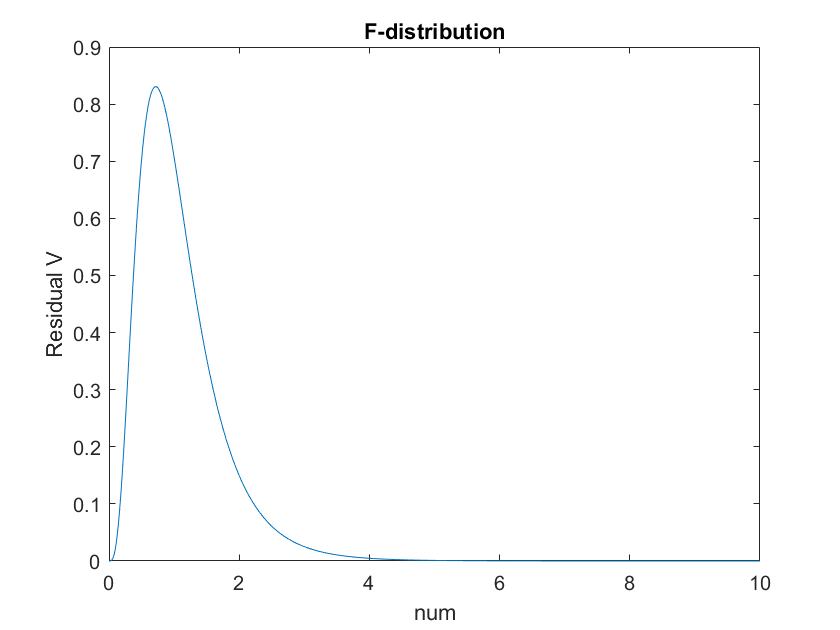

% Plot the F-distribution  pkg load statistics
x_axes = 0:0.01:10;

figure
plot(x_axes,fpdf(x_axes,f1,f2))
title("F-distribution")
xlabel("num")
ylabel("Residual V")

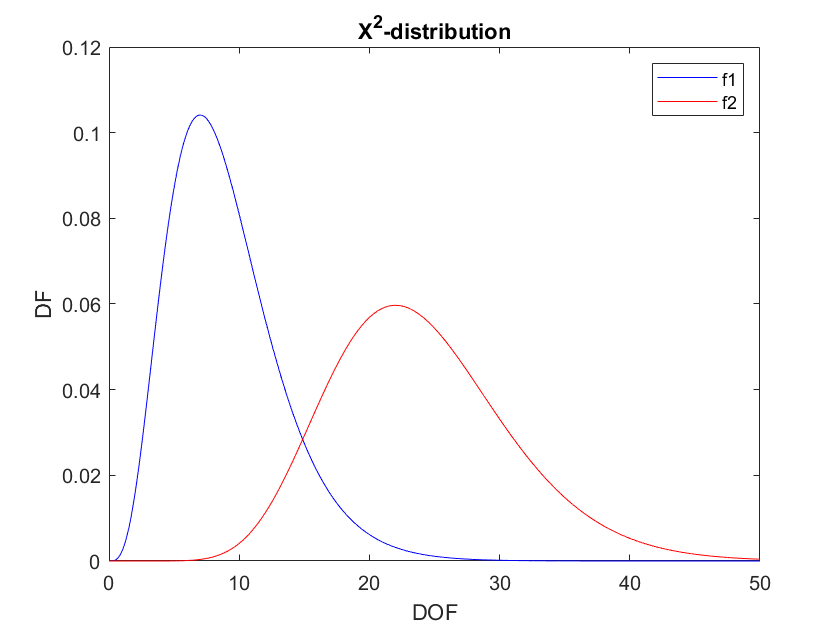


% Plot the x^2 - distribution 
x_axe  = 0:0.01:50;

figure
plot(x_axe ,chi2pdf(x_axe ,f1),'b',x_axe,chi2pdf(x_axe,f2),'r')
title("X^2-distribution")
xlabel("DOF")
ylabel("DF")
legend('f1','f2')

aa